# Problem 1.


$$A = \pmatrix{ 0 & 1 & -2 \cr 1 & 0 & 0 \cr 1 & 0 & 1}$$
 
$$b = \pmatrix{0 \cr 0.6 \cr 0.82}$$



$$C = \pmatrix{1 & 1 & 1}$$
 
$$d = (1)$$


% Constuct survey matrix
A = [0, 1, -2; ...
     1, 0,  0; ...
     1, 0,  1];
 b = [0;0.6;0.82];
 
 % Construct constraint
 C = [1,1,1];
 d = [1];
 
 % Solve constrained least squares problem
 [R,S,T] = svd(C);
 r = rank(C);
 T1 = T(:,1:r);
 T2 = T(:,r+1:end);
 
 % Find z that minimizes the 2-norm using least-squares
 z = (A*T2) \ (b-A*(C\d));
 
 % Use z to get the actual solution
 x = C\d + T2*z

x =     0.6371
    0.2357
    0.1271


 % Check probability condition
 fprintf('x + y + z = %f', sum(x))

x + y + z = 1.000000

After solving the constrained least squares problem, we can see that the roughly 63.7% of the population prefers milk, 23.6% prefers beer, and 12.7% prefers wine. 

# Problem 2.

 % Number of grid points - 1
 N = 24;
 i = 0:N;
 x = (i/N)';
 y = sin(2*pi * x);
 
 x12 = 12/N;
 
 % Constuct block matrix
 A11 = x(1:13).^[0,1,2,3];
 A22 = x(13:25).^[0,1,2,3];
 A21 = zeros(13,4);
 A = [A11 A21;
      A21 A22];
 b = [y(1:13);y(13:25)];
 
 % Constuct constraints
 C = [0,1,2*x12,3*x12^2,0,-1,-2*x12,-3*x12^2;
      1,x12,x12^2,x12^3,-1,-x12,-x12^2,-x12^3];
 d = [0;0];
 
 % Solve constrained least squares problem
 [R,S,T] = svd(C);
 r = rank(C);
 T1 = T(:,1:r);
 T2 = T(:,r+1:end);
 
 % Find z that minimizes the 2-norm using least-squares
 z = (A*T2) \ (b-A*(C\d));
 
 % Use z to get the actual solution
 coeff = C\d + T2*z

coeff =    -0.0326
    8.1888
  -17.1302
    1.7665
    7.2076
  -20.7721
   11.8307
    1.7665


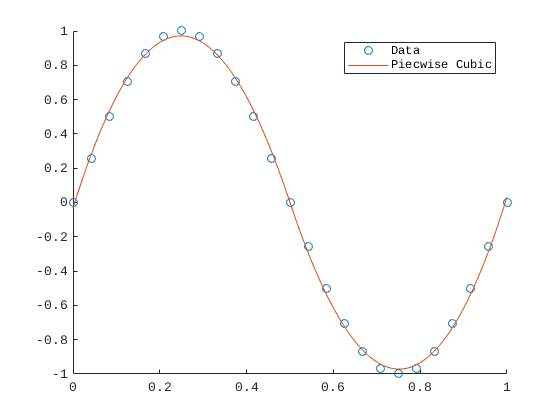

 
 % Plot solution overlayed on data
 X = linspace(0,1,100)';
 Y = zeros(100,1);
 for i = 1:100
     if (X(i) <= 12/N)
         Y(i) = coeff(1) + coeff(2)*X(i) + coeff(3)*X(i)^2 + coeff(4)*X(i)^3;
     else 
         Y(i) = coeff(5) + coeff(6)*X(i) + coeff(7)*X(i)^2 + coeff(8)*X(i)^3;
     end
 end
 
 figure()
 scatter(x,y)
 hold on
 plot(X,Y)
 legend('Data','Piecwise Cubic')

From the plot we can visually see that our constraints of differentiability and continuity were solved. Even though we're only using two cubic functions, we were able to resolve the most important features of the data. we could ultimately fit more piecwise polynomials into the curve, or we could increase the degree of the polynomial to resolve the surface better. 

# Problem 3


$$A^\dagger = (A^T A) ^{-1} A^T = (V \Sigma^T \underset{I}{\underbrace{U^T U}} \Sigma V^T)^{-1} V \Sigma^T U^T = V \Sigma^{-1} (\Sigma^T)^{-1} \underset{I}{\underbrace{V^T V}} \Sigma^T U^T = V (\Sigma^T \Sigma)^{-1} \Sigma^T U^T = V \Sigma^\dagger U^T.$$
